## **Define Image**

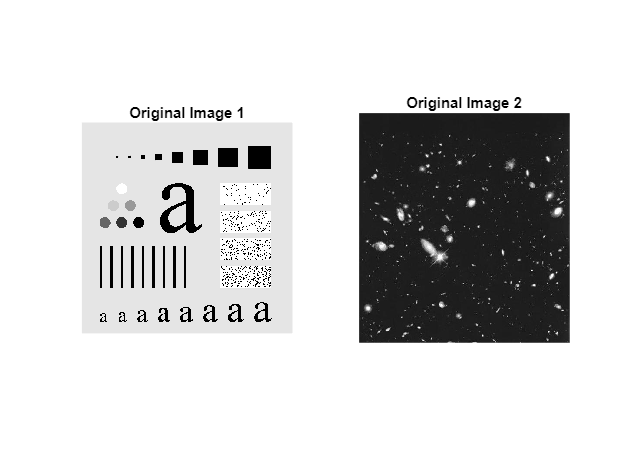

i1 = imread('Fig0333(a)(test_pattern_blurring_orig).tif');
i2 = imread('Fig0334(a)(hubble-original).tif');
figure;
subplot(1, 2, 1), imshow(i1), title('Original Image 1');
subplot(1, 2, 2), imshow(i2), title('Original Image 2');

## **Define and display filters**

box3 = ones(3,3) / 9;
box5 = ones(5,5) / 25;
box7 = ones(7,7) / 49;
disp('Box Filters Defined');

Box Filters Defined


## **Apply 3x3 filters**

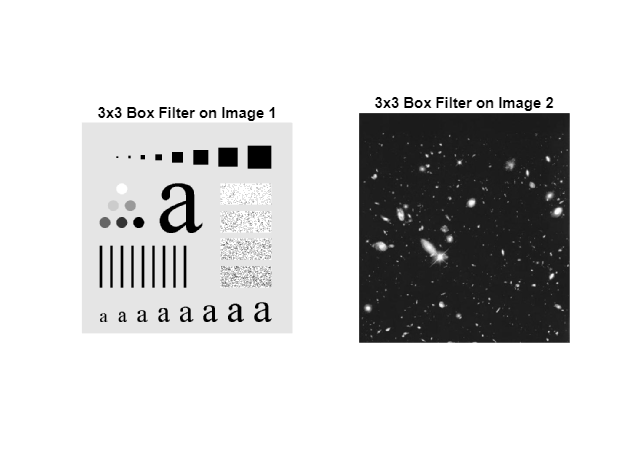

img3_1 = imfilter(i1, box3, 'replicate');
img3_2 = imfilter(i2, box3, 'replicate');
figure;
subplot(1, 2, 1), imshow(img3_1), title('3x3 Box Filter on Image 1');
subplot(1, 2, 2), imshow(img3_2), title('3x3 Box Filter on Image 2');

## **Apply 5x5 filter**

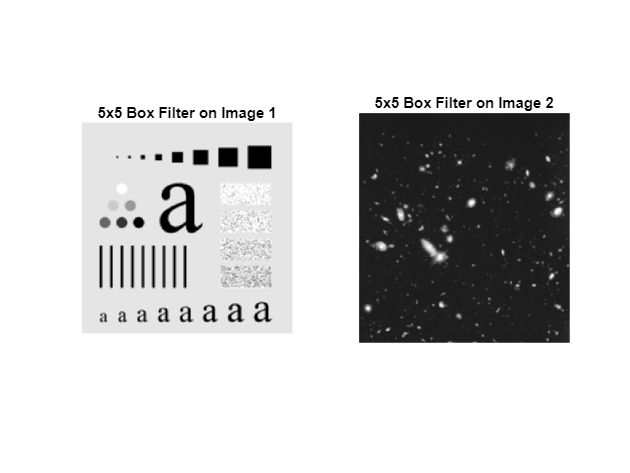

img5_1 = imfilter(i1, box5, 'replicate');
img5_2 = imfilter(i2, box5, 'replicate');
figure;
subplot(1, 2, 1), imshow(img5_1), title('5x5 Box Filter on Image 1');
subplot(1, 2, 2), imshow(img5_2), title('5x5 Box Filter on Image 2');

## Apply 7x7 filters

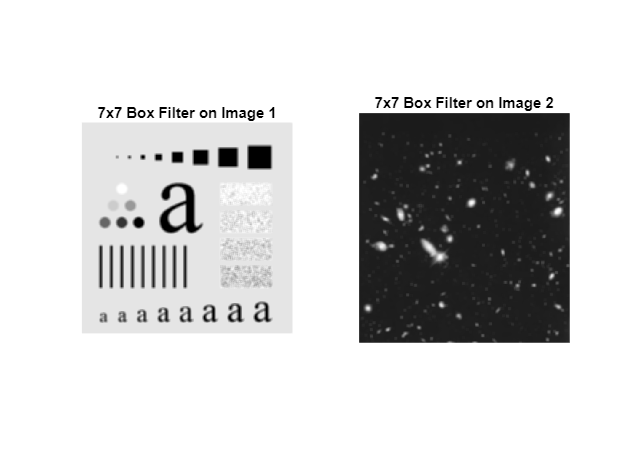

img7_1 = imfilter(i1, box7, 'replicate');
img7_2 = imfilter(i2, box7, 'replicate');
figure;
subplot(1, 2, 1), imshow(img7_1), title('7x7 Box Filter on Image 1');
subplot(1, 2, 2), imshow(img7_2), title('7x7 Box Filter on Image 2');

## **Result**

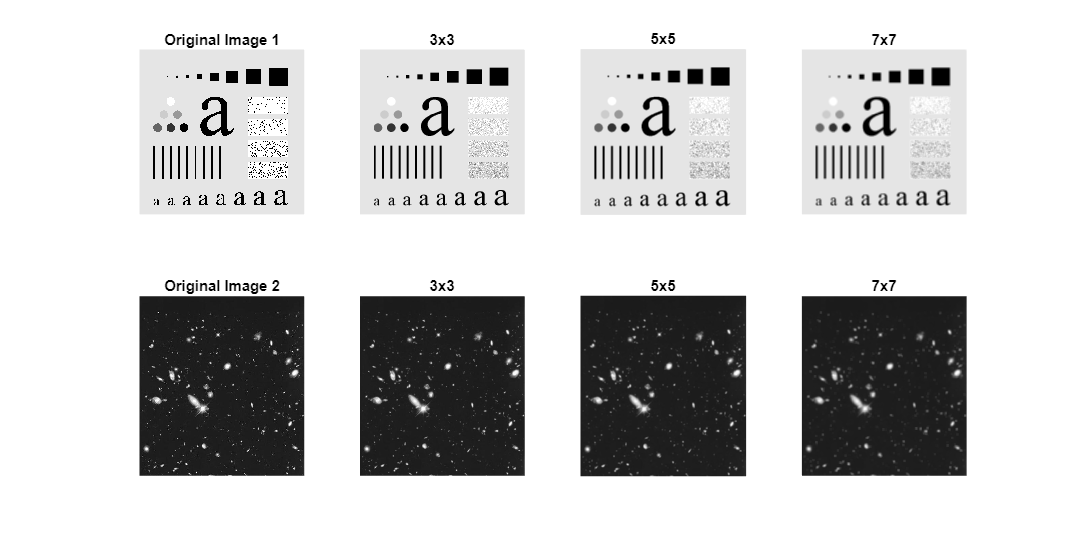

figure('Position', [100, 100, 1400, 700]);

subplot(2, 4, 1), imshow(i1), title('Original Image 1');
subplot(2, 4, 2), imshow(img3_1), title('3x3');
subplot(2, 4, 3), imshow(img5_1), title('5x5');
subplot(2, 4, 4), imshow(img7_1), title('7x7');

subplot(2, 4, 5), imshow(i2), title('Original Image 2');
subplot(2, 4, 6), imshow(img3_2), title('3x3');
subplot(2, 4, 7), imshow(img5_2), title('5x5');
subplot(2, 4, 8), imshow(img7_2), title('7x7');